## **EEGLAB OpenNeuro to DL pipeline**

In this example, we present the pipeline that downloads the [EEG dataset](https://openneuro.org/datasets/ds003061/versions/1.1.2) from the online repository, pre-processes it using [EEGLAB](https://sccn.ucsd.edu/eeglab/index.php) toolbox [2] and formats as input for deep learning-based classification. The recordings were collected by the Healthy Brain Network from 2952 healthy children (age 5-21). The data is stored in a [BIDS](https://bids.neuroimaging.io/) format [3], a standard defining the organization of neuroimaging/accompanying behavioral data, as well as the relevant metadata, facilitating the data sharing and reproducibility.

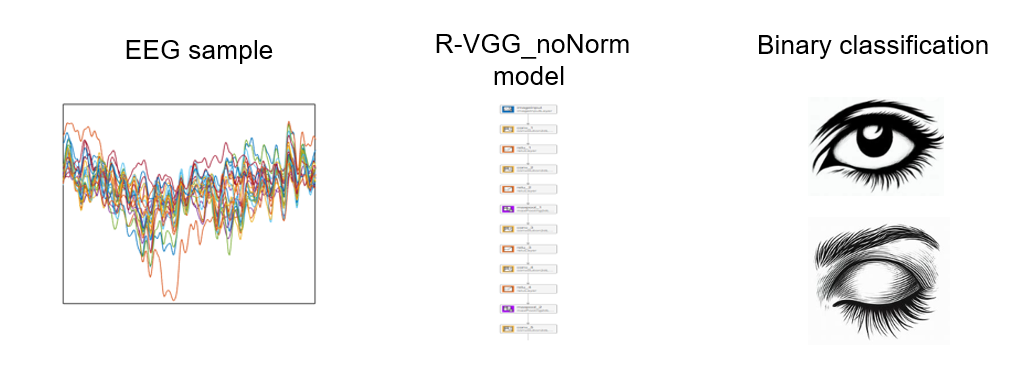

**Background on Dataset**

The dataset consists of a scalp EEG recordings from 33 participants, divided into 56 sessions. Participants were asked to keep the eyes closed for 40 sec and eyes open for 20 sec.

Recording was performed using the standard [**10-20 EEG system**](https://en.wikipedia.org/wiki/10%E2%80%9320_system_(EEG)) (Active Two Biosemi system, Biosemi Inc.), with 500 Hz sampling rate. Eyes-open and eyes-closed periods are divided into non-overlapping individual samples (0.5 sec long).

**Background on Example**

In this example, we are demonstrating the binary classification (eyes open or eyes closed) based on the scalp EEG recordings. 

**BIDS Format**

BIDS format [3] defines the dataset structure and minimum information the dataset needs to contain. The EEG data files could be stored as one of the standard EEG formats (e.g. edf, EEGLAB, NWB). The EEG files in this dataset are stored in *.set format, produced by EEGLAB toolbox. The EEGLAB `pop_importbids` function downloads the BIDS dataset from the online repository and puts it in the EEGLAB format. 

curr_env = getenv; 

if isKey(curr_env,"MW_DDUX_APP_NAME")==1 & curr_env("MW_DDUX_APP_NAME")=='MATLAB_ONLINE'
    environment = 'online';
elseif isKey(curr_env,"MW_DDUX_APP_NAME")==0
    environment = 'local';
end

curr_dir = pwd;
if strcmp(environment, 'online')==1
    addpath MATLAB Add-Ons/Collections/EEGLAB;
    addpath '/MATLAB Drive/Repositories/study_ml';
else
    if exist('eeglab','dir')==1
        eeglab;
    elseif exist('eeglab','dir')==7
        curr_dir = pwd;
        addpath(sprintf('%s/eeglab',curr_dir));
        eeglab;
    else
        curr_dir = pwd;
        gitclone('https://github.com/sccn/eeglab');
        addpath(sprintf('%s/eeglab',curr_dir));
        eeglab;
    end
end

 
gitclone('https://github.com/sccn/bids-matlab-tools');
addpath(sprintf('%s/bids-matlab-tools',curr_dir));
addpath '/MATLAB Drive/Repositories/study_ml';

addpath(sprintf('%s/helper',pwd));


base_dir = pwd;
dataset_ID = 'ds004186';

tic
download_shrink_dataset(dataset_ID);
toc

filePath = sprintf('%s/%s',base_dir,dataset_ID);
out_dir = sprintf('%s/DL',base_dir);
tic
[STUDY, ALLEEG] = pop_importbids_integrated(filePath, environment, 'eventtype', 'value', 'outputdir', out_dir);
toc

The pop_importbids function provides two outputs, **STUDY** (the EEGLAB structure defining the group analysis parameters) and **ALLEEG** (the structure containing all the loaded EEG datasets). 

**ALLEEG** is a structure with the first dimension equaling the number of loaded dataset.

- ALLEEG.**filename** - contains the filenames

- ALLEEG.**subject** - subject labels

- ALLEEG.**chanlocs** - channel labels and respective anatomical coordinates

- ALLEEG.**event** - information on trial timestamps and presented stimuli

- ALLEEG.**data** - EEG time series, organized as a matrix (n of channels x n of samples)

**Exploring the Dataset **

We can check the number of datasets and unique subjects.

dataset_info(ALLEEG);

## Preparing the data for DL training/inference format

`pop_studydl` EEGLAB function exports the EEG signals stored in EEGLAB structure into ML/DL data format. 

tic
if strcmp(environment,'local')==1
    [ALLEEG] = pop_studydl_integrated(STUDY, ALLEEG, environment,'outputdir', fullfile(base_dir, 'ML_EXPORT'));
elseif strcmp(environment,'online')==1
    [ALLEEG, samples_all, sample_ID_all, labels_all] = pop_studydl_integrated(STUDY, ALLEEG, environment, 'outputdir', fullfile(base_dir, 'ML_EXPORT'));
end

toc

for i = 1:numel(sample_ID_all)
    labels_all{i} = sample_ID_all{i}(48:49);
end

### **Data visualization**

Next, we can plot the EEG trace from an example channel, e.g. the first channel from the first dataset.

example_eeg_trace = ALLEEG(1).data(1,:);

figure;plot(example_eeg_trace); xlim([1 numel(example_eeg_trace)]); xlabel('n of samples'); 
ylim([min(example_eeg_trace) max(example_eeg_trace)]); ylabel('voltage'); title(sprintf('%s',ALLEEG(1).chanlocs(1).labels))

## Creating the datastore

selected_labels = {'EC','EO'};

if strcmp(environment,'local')==1
    [ds] = create_datastore(base_dir, selected_labels, environment);
elseif strcmp(environment,'online')==1
    [ds, selected_sample_ID] = create_datastore(base_dir, selected_labels, environment, labels_all, samples_all, sample_ID_all);
end


## Preview the first sample of the datastore

if strcmp(environment,'local')==1
    sample = preview(ds);
elseif strcmp(environment,'online')==1
    sample = preview(ds); sample = sample{1};
end

fprintf('Sample size = %d, %d, %d\n', size(sample));

## Compute class weights if classes are imbalanced

In real life data, classes are often **imbalanced**. The class imbalance is defined as the skewed proportions of individual class samples, which could affect the model training and bias the inference towards the **majority class** (the class with largest proportion of samples). Here is a more detailed [explanation](https://medium.com/nerd-for-tech/class-imbalance-problem-and-ways-to-handle-it-4861a195398a) on the influence of class imbalance on model performance. One of the possible options to deal with the class imbalance is assigning the **class weights, **which set the relative importance of individual classes in training. Class weights are computed by the `compute_class_weights` helper function.

[classProportions, uniqueLabels] = compute_class_proportions(ds,environment)

### Splitting the Datastore

Finally, we can split the datastore and evaluate the model performance. 

splitting_mode = "subjects_mixed";

if strcmp(environment,'local')==1
[train_ds, val_ds, test_ds] = split_datastore(ds, splitting_mode, environment, selected_labels, base_dir);
elseif strcmp(environment, 'online')==1
[train_ds, val_ds, test_ds] = split_datastore(ds, splitting_mode, environment, selected_labels, base_dir, selected_sample_ID);
end


**Creating the Balanced Dataset**

One way of improving the model performance would be to provide the balanced dataset, where the proportions of different classes are approximately equal. The `create_balanced_dataset` helper function performs this step, by dropping the subset of majority class samples. 

In the drop-down menu below, you can indicate whether to use the **balanced** or **original** dataset.

"balanced"

dataset = ans; 

if strcmp(dataset,'balanced')==1
    [train_ds val_ds test_ds] = create_balanced_dataset(train_ds, val_ds, test_ds, environment);
    [classProportions, uniqueLabels] = compute_class_proportions(train_ds, environment)
end

## Constructing & Training Network

Here we construct a modified VGG model, which is a simple to understand yet powerfull deep learning model [4]. This model represents a convolutional neural network with 27 layers, with the input layer (`imageInputLayer`) corresponding to the individual sample dimensions and the output layer (`classificationLayer`) reflecting the number of class labels. A detailed explanation of the concept of convolutional neural networks and an overview of individual components (layers, activation functions etc.) may be found [here](https://en.wikipedia.org/wiki/Convolutional_neural_network).

MATLAB `classificationLayer` function, which constructs the neural network **classification output layer**, provides the optional parameter classWeights to account for class weights in training process. 

if strcmp(environment,'local')==1
    classes = unique(train_ds.Labels);
    sample_size = size(preview(train_ds));
elseif strcmp(environment,'online')==1
    classes = categorical(selected_labels);
     sample = preview(train_ds); sample_size = size(sample{1});
end
    num_labels = numel(classes);

    
layers = [
    imageInputLayer(sample_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer('Name','classoutput','Classes', classes)]; 


Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

maxEpochs = 20;

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'ValidationData', val_ds, ... the datastore containing validation labels
    'Plots','training-progress',...% allows the real-time monitoring of training progress
    'MaxEpochs',maxEpochs, ...% the n of training epochs. All the samples are presented once during a single epoch.
    'MiniBatchSize',40);

eeg_net = trainNetwork(train_ds,layers,options);

## Testing Trained Network

Finally, classification accuracy is tested against the testing data and expressed as the percentage of correct classifications.

ds_all{1} = train_ds; ds_all{2} = val_ds; ds_all{3} = test_ds;

str_array = ["train" "val" "test"];

for i = 1:numel(str_array)
    curr_ds = ds_all{i};
    [YPred] = classify(eeg_net, curr_ds);
    if strcmp(environment,'local')==1
        curr_performance = sum(0+(curr_ds.Labels == YPred))/length(YPred);
    elseif strcmp(environment,'online')==1
        dataout = readall(curr_ds,UseParallel=true);
        labels_cell = dataout(:,2);
        for x  = 1:numel(labels_cell)
        if YPred(x) == categorical(labels_cell{x})
            curr_performance(x)=1;
        else
            curr_performance(x)=0;
        end
        end
    end
    performance_all(i) = mean(curr_performance);
    fprintf('Percent correct %s is %1.2f %%\n', str_array(i), mean(curr_performance)*100); clear curr_performance;
end


figure;bar(performance_all(2)*100);
title('prediction accuracy')
ylabel('prediction accuracy (%)');
xticks([]);yticks([0 50 100]);yticklabels({'0','50','100'});ylim([0 100])


**Contributors:**

### **References**

[1] Gorgolewski, K., Esteban, O., Schaefer, G., Wandell, B. and Poldrack, R., 2017. OpenNeuro—a free online platform for sharing and analysis of neuroimaging data. *Organization for human brain mapping. Vancouver, Canada*, *1677*(2).

[2] Delorme, A. and Makeig, S., 2004. EEGLAB: an open source toolbox for analysis of single-trial EEG dynamics including independent component analysis. *Journal of neuroscience methods*, *134*(1), pp.9-21.

[3] Pernet, C.R., Appelhoff, S., Gorgolewski, K.J., Flandin, G., Phillips, C., Delorme, A. and Oostenveld, R., 2019. EEG-BIDS, an extension to the brain imaging data structure for electroencephalography. *Scientific data*, *6*(1), p.103.